## **Smart Throttle Control_Tejavath Srinivas_241098_ Assgn3 **

## Problem 1: Lead Compensator for Speed Improvement

(a) Baseline PID

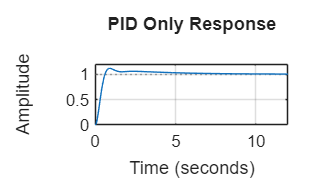

G = 20/(s*(s+2)*(s+5));

% (a) Baseline PID
C_pid = pidtune(G,'PID');
T_pid = feedback(C_pid*G,1);

figure;
step(T_pid)
grid on
title('PID Only Response')


pid_info = stepinfo(T_pid)

pid_info = struct with fields:
         RiseTime: 0.4083
    TransientTime: 5.9509
     SettlingTime: 5.9509
      SettlingMin: 0.9285
      SettlingMax: 1.1154
        Overshoot: 11.5379
       Undershoot: 0
             Peak: 1.1154
         PeakTime: 0.9107


(b) Lead Compensator

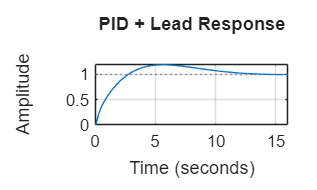

z = 3; p = 15; K = 1;
C_lead = K*(s+z)/(s+p);

C_total = C_pid*C_lead;
T_total = feedback(C_total*G,1);

figure;
step(T_total)
grid on
title('PID + Lead Response')


lead_info = stepinfo(T_total)

lead_info = struct with fields:
         RiseTime: 2.0745
    TransientTime: 12.1338
     SettlingTime: 12.1338
      SettlingMin: 0.9002
      SettlingMax: 1.1838
        Overshoot: 18.3815
       Undershoot: 0
             Peak: 1.1838
         PeakTime: 5.6150


(c) Comparison

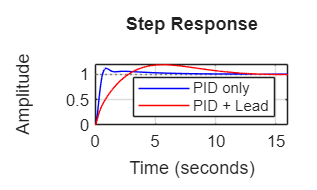

figure;
step(T_pid,'b',T_total,'r')
legend('PID only','PID + Lead')
grid on


Comparison = table( ...
    [pid_info.RiseTime; lead_info.RiseTime], ...
    [pid_info.SettlingTime; lead_info.SettlingTime], ...
    [pid_info.Overshoot; lead_info.Overshoot], ...
    'RowNames',{'PID Only','PID + Lead'}, ...
    'VariableNames',{'RiseTime','SettlingTime','Overshoot'})

Comparison = 2×3 table
                  RiseTime    SettlingTime    Overshoot
                  ________    ____________    _________

    PID Only      0.40833        5.9509        11.538  
    PID + Lead     2.0745        12.134        18.382  


(d) Zero–Pole Variations

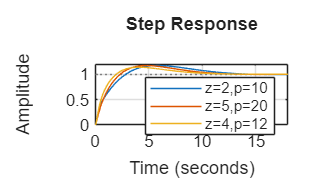

pairs = [2 10; 5 20; 4 12];

figure; hold on;
for i = 1:size(pairs,1)
    z = pairs(i,1);
    p = pairs(i,2);
    C_lead = (s+z)/(s+p);
    T = feedback(C_pid*C_lead*G,1);
    step(T)
end
legend('z=2,p=10','z=5,p=20','z=4,p=12')
grid on
hold off

## Problem 2: Lag Compensator for Steady-State Accuracy

(a) P Controller

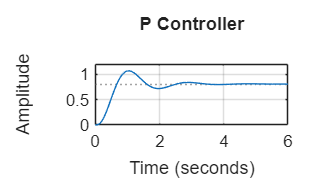

G = 50/((s+1)*(s+3)*(s+8));

% (a) P Controller
Kp = 2;
T_p = feedback(Kp*G,1);

figure;
step(T_p)
grid on
title('P Controller')


p_info = stepinfo(T_p);
ess_p = abs(1 - dcgain(T_p))

ess_p = 0.1935

(b) Lag Compensator

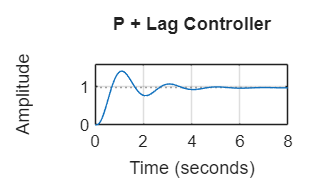

z = 1; p = 0.1;
Clag = (s+z)/(s+p);

T_lag = feedback(Kp*Clag*G,1);

figure;
step(T_lag)
grid on
title('P + Lag Controller')


lag_info = stepinfo(T_lag);
ess_lag = abs(1 - dcgain(T_lag))

ess_lag = 0.0234

(c) Error Comparison Table

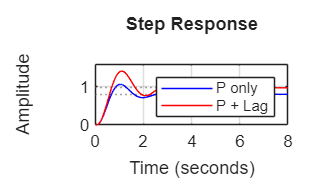

figure;
step(T_p,'b',T_lag,'r')
legend('P only','P + Lag')
grid on


Lag_Table = table( ...
    [ess_p; ess_lag], ...
    [p_info.SettlingTime; lag_info.SettlingTime], ...
    'RowNames',{'P Only','P + Lag'}, ...
    'VariableNames',{'SteadyStateError','SettlingTime'})

Lag_Table = 2×2 table
               SteadyStateError    SettlingTime
               ________________    ____________

    P Only          0.19355           3.2198   
    P + Lag        0.023438           5.2126   


(d) Trade-off (Pole Shift)

## Problem 3: Feedforward + Feedback Control

(a) Feedback Only

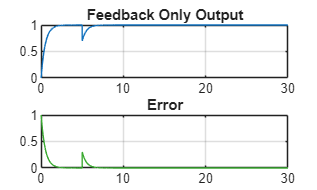

G = 1/(s+0.5);
C = 2 + 1/s;

t = 0:0.01:30;
r = ones(size(t));
d = 0.3*(t>=5);

T = feedback(C*G,1);
S = feedback(1,C*G);

y_fb = lsim(T,r,t) - lsim(S,d,t);
e_fb = r - y_fb;

figure;
subplot(2,1,1)
plot(t,y_fb), grid on, title('Feedback Only Output')

subplot(2,1,2)
plot(t,e_fb), grid on, title('Error')

(b) Feedforward + Feedback

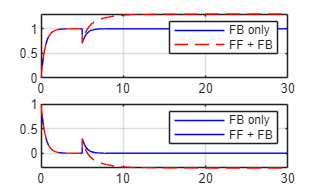

Kff = 1/dcgain(G);

y_ff = lsim(T,r,t) - lsim(S,d,t) + lsim(G*Kff,d,t);
e_ff = r - y_ff;

figure;
subplot(2,1,1)
plot(t,y_fb,'b',t,y_ff,'r--')
legend('FB only','FF + FB')
grid on

subplot(2,1,2)
plot(t,e_fb,'b',t,e_ff,'r--')
legend('FB only','FF + FB')
grid on

(d) Unpredicted Disturbance Test:

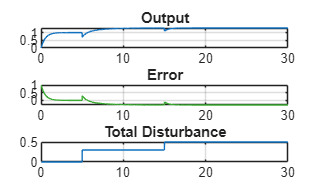

d2 = d + 0.2*(t>=15);

y = lsim(T,r,t) - lsim(S,d2,t) + lsim(G*Kff,d,t);
e = r - y;

figure;
subplot(3,1,1)
plot(t,y), grid on, title('Output')

subplot(3,1,2)
plot(t,e), grid on, title('Error')

subplot(3,1,3)
plot(t,d2), grid on, title('Total Disturbance')

## Problem 4: Simple MIMO System Control

(a) Open-Loop MIMO Analysis:

G11 = 2/(s+1);
G12 = 0.5/(s+2);
G21 = 1/(s+1.5);
G22 = 3/(s+1);

G = [G11 G12; G21 G22];

t = (0:0.01:20)';


b) Decentralized PI Control:

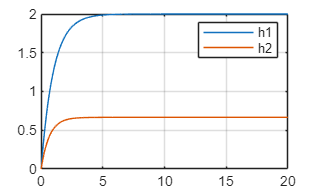

U = [ones(size(t)) zeros(size(t))];
Y = lsim(G,U,t);

figure;
plot(t,Y(:,1),t,Y(:,2))
legend('h1','h2')
grid on

c) Decentralized PI Control

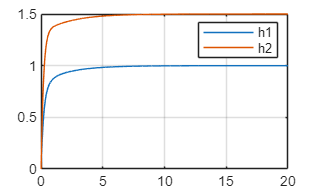

C1 = 1.5 + 0.8/s;
C2 = 1.2 + 0.6/s;

C = [C1 0; 0 C2];
T = feedback(G*C,eye(2));

r1 = ones(size(t));
r2 = 1.5*ones(size(t));
R = [r1 r2];

Y = lsim(T,R,t);

figure;
plot(t,Y(:,1),t,Y(:,2))
legend('h1','h2')
grid on

d) Sequential Setpoint Change

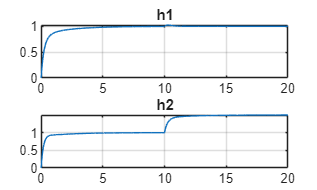

r2 = ones(size(t));
r2(t>=10) = 1.5;
R = [r1 r2];

Y = lsim(T,R,t);

figure;
subplot(2,1,1)
plot(t,Y(:,1)), grid on, title('h1')

subplot(2,1,2)
plot(t,Y(:,2)), grid on, title('h2')

## Summary Questions

**1. When would you choose a lead compensator over increasing PID gains?**

A lead compensator is used when faster response is required without causing instability or excessive overshoot, which often happens when PID gains are increased.

**2. What are the main advantages and limitations of lag compensators?**

Lag compensators reduce steady-state error by increasing DC gain but slow down the system and increase settling time.

**3. Why is feedforward control called “proactive”?**

Feedforward control acts in advance using known disturbance or reference information, whereas feedback reacts only after an error occurs.

**4. What makes MIMO systems more difficult than SISO systems?**

In MIMO systems, each input affects multiple outputs, causing coupling and interaction, which makes control design and tuning more complex.